x, y軸の設定

n = 11; % n列目
m = 13; % m列目
N = [n, m]

N =     11    13


c = 0.5

c = 0.5000

%     data(:, 5) =(data(:, 1) - valueToSubtractFx) .* 100; % Fxの計算
%     data(:, 6) = (data(:, 2) - valueToSubtractFy)  .* 100; % Fyの計算
%     data(:, 7) = (data(:, 3) - valueToSubtractX) .* 100 ./ 50; % epsilonXの計算
%     data(:, 8) = (valueToSubtractY - data(:, 4)) .* 100 ./ 50; % epsilonYの計算
%     data(:, 9) = data(:, 7) .* 0.853; % 真のepsilonXの計算
%     data(:, 10) = data(:, 8) .* 0.853; % 真のepsilonYの計算
%     data(:, 11) = data(:, 9) + 1; % lambdaXの計算
%     data(:, 12) = data(:, 10) + 1; % lambdaYの計算
%     data(:, 13) = data(:, 5) ./ 31.25; % sigmaXの計算
%     data(:, 14) = data(:, 6) ./ 31.25; % sigmaYの計算
%     data(1, 15) = 0; % deltaXの初期値
%     data(1, 16) = 0; % deltaYの初期値
%     data(2:end, 15) = diff(data(:, 11)); % deltaXの計算
%     data(2:end, 16) = diff(data(:, 12)); % deltaYの計算
%     data(:, 17) = data(:, 13) .* data(:, 15); % wiXの計算
%     data(:, 18) = data(:, 14) .* data(:, 16); % wiYの計算
%     data(:, 19) = data(:, 11) .^ 2 + data(:, 12) .^ 2 + (1 ./ (data(:, 11) .* data(:, 12)))  .^ 2; % I1の計算
%     data(:, 20) = (data(:, 11) .* data(:, 12)) .^2 + (data(:, 12) .* (1 ./ (data(:, 11) .* data(:, 12)))) .^2 + ((1 ./ (data(:, 11) .* data(:, 12))) .* data(:, 11)) .^2; % I2の計算
%     data(:, 21) = cumsum(data(:, 17)) + cumsum(data(:, 18)) % Wの計算

virginLoading, reLoading, unLoadingのプロット(uniaxial)

% CSVファイルが保存されているフォルダのパスを指定
plotdata2D('DataPath', c, N)

fileList = フィールドをもつ 38×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 38

k = 0

k = 34

k = 83

k = 134

k = 184

k = 234

k = 283

k = 334

k = 384

k = 435

k = 484

k = 509

k = 535

k = 560

k = 585

k = 609

k = 634

k = 658

k = 684

k = 709

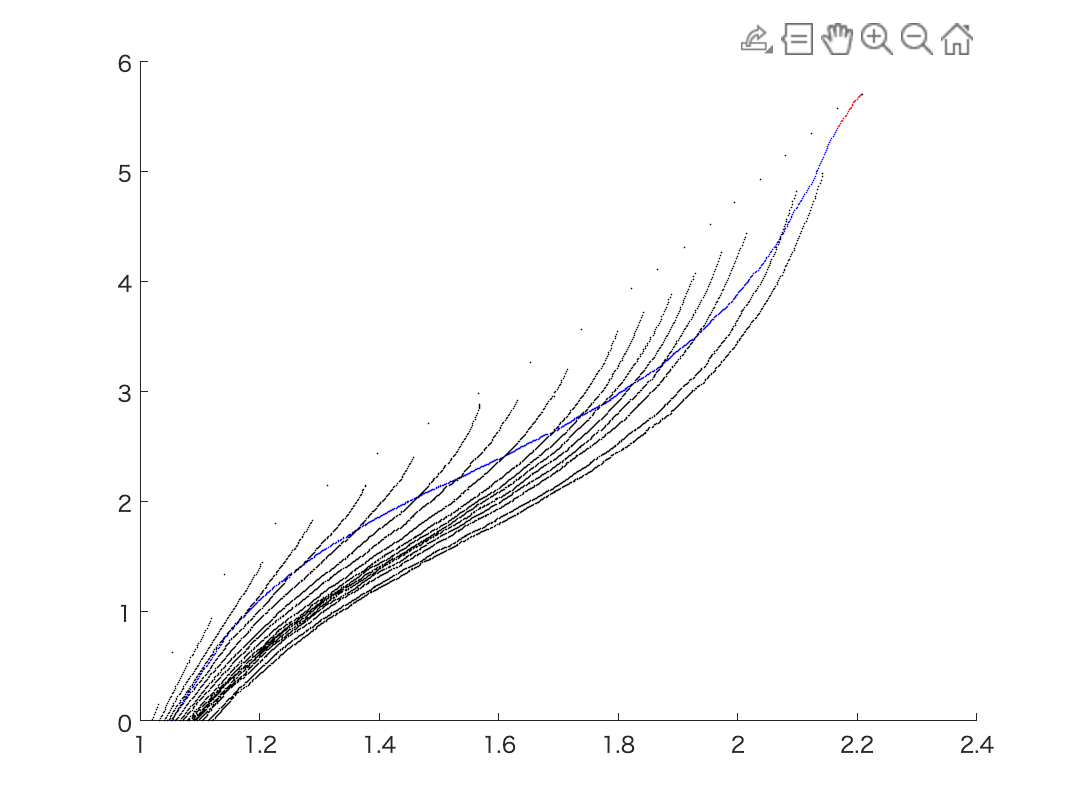

fileList = フィールドをもつ 37×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 37

k = 0

k = 33

k = 81

k = 130

k = 181

k = 227

k = 275

k = 329

k = 379

k = 425

k = 473

k = 525

k = 576

k = 624

k = 668

k = 720

k = 768

k = 821

k = 863

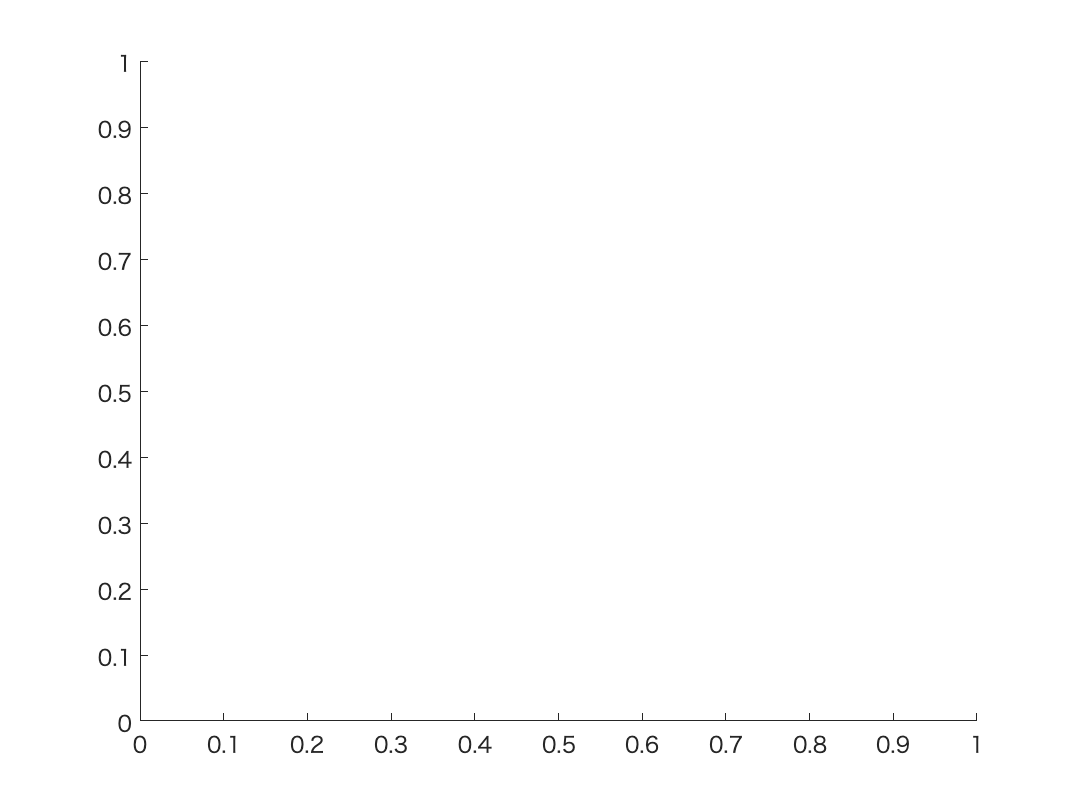

位置 1 のインデックスが配列範囲を超えています。インデックスは 37 を超えてはなりません。

エラー: plotdata2D>plotdata2D (行 77)
    xData = data(1:k, N(1));


xlim([1, 2.4])
ylim([0, 6])

virginLoading, reLoading, unLoadingのプロットfunction

function output = plotdata2D(A, c, N)
% CSVファイルが保存されているフォルダのパスを指定
folderPath = A;

% フォルダ内のCSVファイルのリストを取得
fileList = dir(fullfile(folderPath, '*.csv'))

% ファイル数を取得
numFiles = numel(fileList)

% ループを使用して各CSVファイルについてプロットを行う
k = 0 % kの初期化
for i = 1:ceil(numFiles/2)
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    data = readmatrix(filePath);

    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(k + 1:end, N(1));
    yData = data(k + 1:end, N(2));

    % プロット
    
    scatter(xData, yData, c, "r", 'filled')
    

    if k > 0
    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(1:k, N(1));
    yData = data(1:k, N(2));
    
    end

    k = numel(data(:, 1)) % kの更新

    % プロット
    hold on
    scatter(xData, yData, c, "b", 'filled')
    hold off
end

% ループを使用して各CSVファイルについてプロットを行う
for i = ceil(numFiles/2) + 1 : numFiles
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    data = readmatrix(filePath);
    
    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(:, N(1));
    yData = data(:, N(2));
    

    % プロット
    hold on
    scatter(xData, yData, c, "k", 'filled')
    hold off
end

end